# Annexe

Fait en matlab R2020a.

clc; clear all; close all;

## Definition of parameters

global Vo Vi R L C Q Qf rho T N h beta k_max A1 A2 B1 B2 x_ref s_ref t

Vo = 15;
Vi = 10;
R = 20;
L = 0.3;
C = 0.1;
Q = eye(2);
Qf = Q;
rho = 1;
T = 5;
N = 100;
h = T/N;
epsilon = 10^(-6);
beta = 0.5;
k_max = 25;
t = linspace(0, T, N);

Calculation of duty cycle

% La formule for buck-boost is defined

s_ref = Vo/(Vo + Vi);

Calculation of the corresponding current

il = Vo/(R*(1-s_ref));

x_ref = [il; Vo];

Matrices

A1 = [0, 0; 0, -1/(R*C)];
A2 = [0, -1/L; 1/C, -1/(R*C)];
B1 = [1/L; 0];
B2 = [0; 0];

## Algorithm FBS

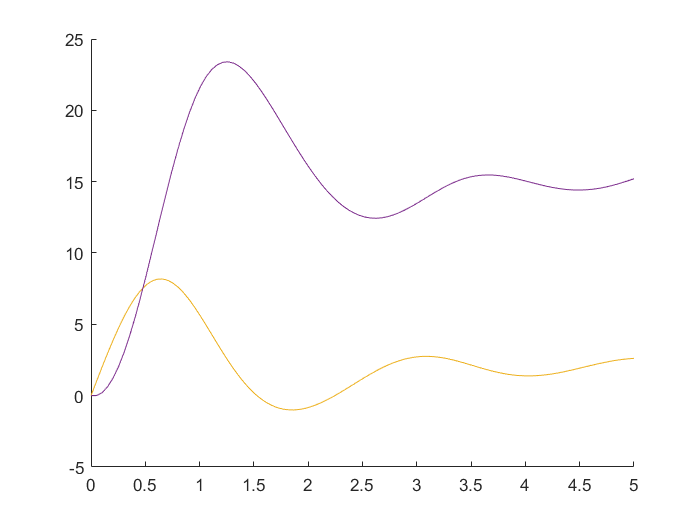

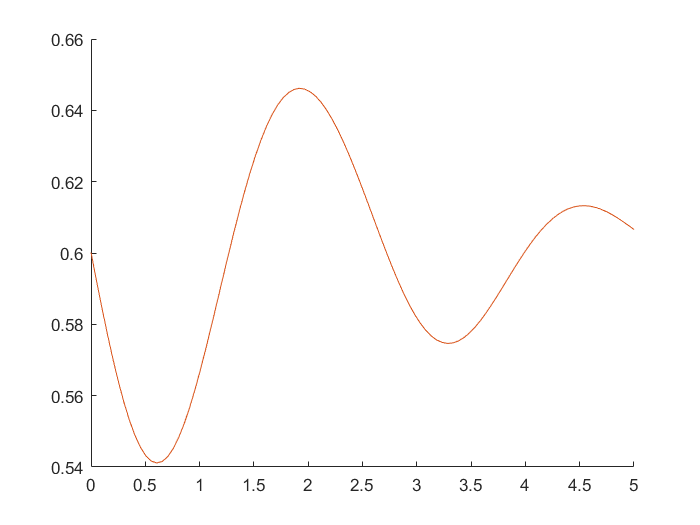

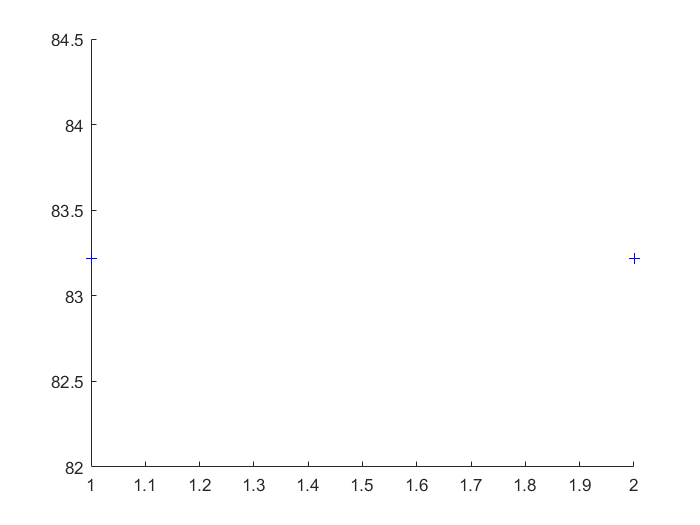

s = s_ref*ones(1, N);

X = discretX(s);

J_old = 0;
s_old = s_ref;
p = 1;
Test = true;

while Test && p < 100

    X = discretX(s);
    lbd = discretLambda(X, s);
    v = discretV(X, lbd);
    
    [X_min, s_min, J_min] = minimisation(X, s, v);
    
    figure(1)
    hold on
    plot(t, X_min(1, :), t, X_min(2, :))
    figure(2)
    hold on
    plot(t, s_min)
    figure(3)
    hold on
    plot(p, J_min, '+b')
    
    Test = (abs(J_old - J_min) > 1e-3) || (abs(J_old - J_min) > 10^(-6));
    J_old = J_min;
    s_old = s_min;
    p = p + 1;
    
end

## Fonctions utilisées

function [X_min, s_min, J_min] = minimisation(X, s, v)

global k_max N beta

sp = zeros(k_max, N);
Xp = zeros(2*k_max + 2, N);
Jp = zeros(1, k_max);

Xp(1:2, :) = X;
Jp(1) = discretJ(X, s);

for i = 1 : k_max
    sp(i, :) = max(min(s + (beta^(i))*(v - s), 1), 0);
    Xp(2*(i - 1) + 1 : 2*i, :) = discretX(sp(i, :));
    Jp(1, i) = discretJ(Xp(2*i - 1 : 2*i, :), sp(i, :));
end

[J_min, indiceMin] = min(Jp);
s_min = sp(indiceMin, :);
X_min = Xp(2*indiceMin - 1 : 2*indiceMin, :);

end


function [X] = discretX(s)

global N Vi A1 A2 B1 B2 h

X = zeros(2, N);

for i = 1 : N - 1
    % equation du modele non lineaire
    x_dot = s(i)*(A1*X(:, i) + B1*Vi) + (1 - s(i))*(A2*X(:, i) + B2*Vi);
    % integration du x_dot en utilisant le methode Euler
    X(:, i + 1) = X(:, i) + h*(x_dot);
end

end


function [v] = discretV(X, lbd)

global N s_ref A1 A2 B1 B2 Vi rho

v = zeros(1, N);

for i = 1 : N
    v(i) = s_ref + (lbd(:, i)'*((A2- A1)*X(:, i) + (B2 - B1)*Vi))/rho;
end

end


function [lbd] = discretLambda(X, s)

global N Q x_ref h A1 A2

lbd = zeros(2, N);
lbd(:, N) = Q*(X(:, N) - x_ref);

for i = 1 : N - 1
    lbd(:, N - i) = lbd(:, N - i + 1) + h*(s(N - i + 1)*(A1 - A2)'*lbd(:, N - i + 1) + A2'*lbd(:, N - i + 1) + Q*(X(:, N - i + 1) - x_ref));
end

end


function [J] = discretJ(X, s)

global N h x_ref Q rho s_ref

J = 0;

for i = 1 : N
    J = J + (h/2)*((X(:, i) - x_ref)'*Q*(X(:, i) - x_ref) + rho*(s(i) - s_ref)^2);
end

J = J + 0.5*(X(:, N) - x_ref)'*Q*(X(:, N) - x_ref);

end